% dice simulator & repeated experiments

numRolls = 10

target_side = 6

numSides = 6

How many 6s have we got?
4


% ---parameters---
% repetition
n_repetition = 500

n_repetition = 500

% number of dice rolls
numRolls = 10

numRolls = 10

% target side
target_side = 6

target_side = 6


% ---simulation [n_repetition] times---
% number of dice sides
numSides = 6

numSides = 6

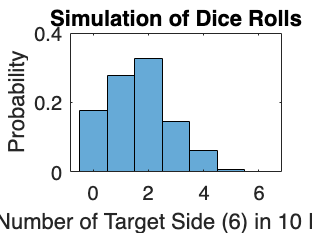

% simulation
% preallocate array to store counts of target side for each repetition
counts = zeros(1, n_repetition);

for rep = 1:n_repetition
    % simulate dice rolls
    diceResults = randi([1, numSides], 1, numRolls);
    
    % count occurrences of the target side
    count = sum(diceResults == target_side);
    % store the count
    counts(rep) = count;
end

% plot histogram of counts
figure;
histogram(counts, 'Normalization', 'probability');
xlabel('Number of Target Side (6) in 10 Rolls');
ylabel('Probability');
title('Simulation of Dice Rolls');

% binomial distribution

% ---parameters---
% number of trials
n = 7

n = 7

% probability of success in a single trial
p = 1/4

p = 0.2500


% ---prepare an array for plotting---
% number of successful trials, range: 0, 1, 2, ..., n
x = 0:1:n

x =      0     1     2     3     4     5     6     7


% probability based on binomial distribution
P_bino = (factorial(n) ./ (factorial(x) .* factorial(n - x))) .* (p.^x) .* ((1 - p).^(n - x))

P_bino =     0.1335    0.3115    0.3115    0.1730    0.0577    0.0115    0.0013    0.0001


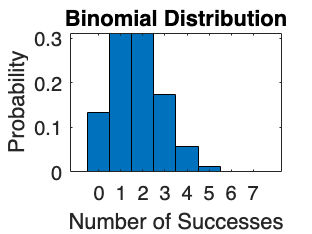

% or you can use this command
% P_bino = binopdf(x,n,p)



% ---plot the binomial distribution---
figure
box on
bar(x, P_bino, 'BarWidth', 1, 'EdgeColor', 'k');
xlabel('Number of Successes')
ylabel('Probability')
title('Binomial Distribution')